% Init

%clears and runs previous groups script
clear all
cd('C:\Users\User\OneDrive\DTU\DTU 4-2-2020\DTU\6. semester\bachelor projekt\Previous work\Bachelor-main\Bachelor-main\Simulation_Bachelor_Project\Matlab')
Drone_2M_Code;

Ktrust = 1.2108e-04

droneMass = 0.4800

Dist = 0.6092

TubeDiag = 0.2300

TubeRot = -1.0240

height_test = 3

hoverControl = 360.8320


%init values for added features
rtiuse=0;
ratiuse = 0;
pvti=1;
pvtiuse=0;
pati=1;
patiuse=0;
yvImax=100000;
yvImin=-100000;
yvOutMax=10000;
yvOutMin=-10000;
yawvImax=100000;
yawvImin=-100000;
yawvOutMax=10000;
yawvOutMin=-10000;
yaw_D_FB= 0;%1=feedback branch active, 0=not
yaw_D_FF= 1;%1=forward branch active, 0=not
yawvtd_FF=0.215;
yawval_FF=0.3;
stepYaw=0;
stepRoll=0;
stepPitch=0;

%Set refference values:
x_ref=0,x_steptime=0

x_ref = 0

x_steptime = 0

y_ref=0,y_steptime=0

y_ref = 0

y_steptime = 0

z_ref=1,z_steptime=0

z_ref = 1

z_steptime = 0

SIM_TIME=30

SIM_TIME = 30

simout=sim(model,SIM_TIME);

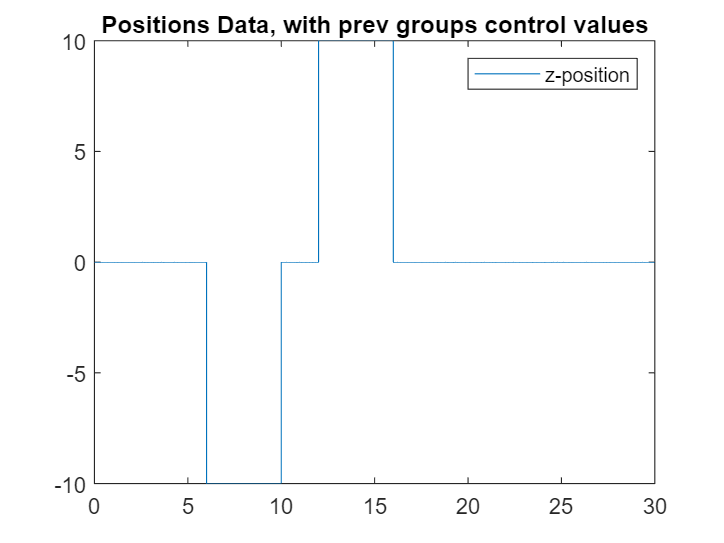

%plotting position data
positionData=simout.logsout.getElement(4).Values.Data;
yawData=simout.logsout.getElement(3).Values.Data;
uYawData=simout.logsout.getElement(2).Values.Data;
yawRefData=simout.logsout.getElement(1).Values.Data;
t=simout.logsout.getElement(4).Values.Time;

plot(t,positionData)
title("Positions Data, with prev groups control values")
legend("z-position","y-position","x-position")

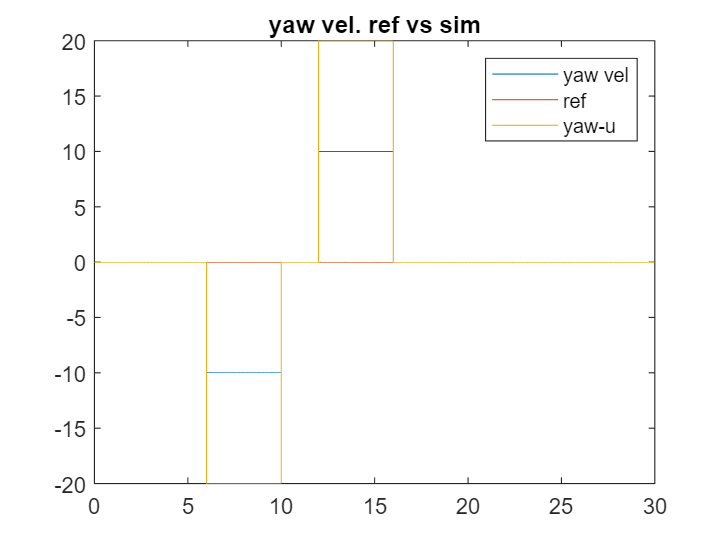

plot(t,[yawData,yawRefData,uYawData])
title("yaw vel. ref vs sim")
legend("yaw vel","ref","yaw-u")

## Control values OLD

%for each controller we have:
%kp=K_P
%td=tau_d
%al=alpha
%ti=tau_i
%iuse=disable/enable integrator

% height velocity
hvkp = 50;
hval = 1;
hvtd = 1;
hvti = 1;
hviuse = 0;
% Height position
h1kp = 1.2; 
h1td = 0.5;
h1al = 1;
h1ti = 1000;
h1iuse = 0; 

% roll velocity
rkp = 0.9539*4; 
rtd = 0.3205;
ral = 0.5;
rti = 1;
rtiuse=0;
% roll angle
rakp = 3.9;
ratd = 0.32;
raal = 0.2;
rati = 100;
ratiuse = 0;

% pitch velocity
pvkp=0.4503*20; % 0.4503
pvtd=0.4428; %0.4428
pval=0.6;
pvti=1;
pvtiuse=0;
% pitch angle
pakp=3.3497; %pakp=3.3497
patd=0.4793;
paal=0.1;
pati=1;
patiuse=0;

%Yaw angle
yakp=2.2791;
yatd=1.0872;
yati=100;
yatiUse=0;
%hvorfor er der ikke nogen alpha???
%Yaw velocity
yawvkp=0.1652;
yawvtd=0.8041;
yawval=0.3;
yawvti=1.5415;
yawvtiUse=0;
%skal integratoren ikke have hoverControl som init cond???

%x vel
xvkp=0.03; %0.1684
xvtd=0.7443;
xval=0.6;
xvti=100;
xvtiUse=0;
%x pos
xkp=1.06741;
xtd=1.5808;
xal=0.1;
xti=100;
xtiUse=1;

%y vel
yvkp=0.1358;
yvtd=0.8433;
yval=0.7;
yvti=100;
yvtiUse=0;
%y pos
ykp=0.5231;
ytd=2.4413;
yal=0.1;
yti=3.8601;
ytiUse=1;


## Control values NEW

%for each controller we have:
%kp=K_P
%td=tau_d
%al=alpha
%ti=tau_i
%iuse=disable/enable integrator

% height velocity
hvkp = 50;
hval = 1;
hvtd = 1;
hvti = 1;
hviuse = 0;
% Height position
h1kp = 1.2; 
h1td = 0.5;
h1al = 1;
h1ti = 5; %%%%%%%%%%%%%%%%%%%%%%%%%%%
h1iuse = 1; %%%%%%%%%%%%%%%%%%%%%%%%%

% roll velocity
rkp = 0.9539*4; 
rtd = 0.3205;
ral = 0.5;
rti = 1;
rtiuse=0;
% roll angle
rakp = 3.9;
ratd = 0.32;
raal = 0.2;
rati = 100;
ratiuse = 0;

% pitch velocity
pvkp=0.4503*20; % 0.4503
pvtd=0.4428; %0.4428
pval=0.6;
pvti=1;
pvtiuse=0;
% pitch angle
pakp=3.3497; %pakp=3.3497
patd=0.4793;
paal=0.1;
pati=1;
patiuse=0;

%Yaw angle
yakp=2.2791;
yatd=1.0872;
yati=100;
yatiUse=0;
%hvorfor er der ikke nogen alpha???
%Yaw velocity
yawvkp=1;
yaw_D_FB= 0;%1=feedback branch active, 0=not
yaw_D_FF= 1;%1=forward branch active, 0=not
yawvtd=0.215;
yawval=0.3;
yawvtd_FF=0.215;
yawval_FF=0.3;
yawvti=1.5415;
yawvtiUse=0;
yawvImax=1000;
yawvImin=-1000;
yawvOutMax=   100000;
yawvOutMin=-  100000;
%skal integratoren ikke have hoverControl som init cond???

%x vel
xvkp=0.1684;
xvtd=0.7443;
xval=0.6;
xvti=100;
xvtiUse=0;
%x pos
xkp=1.06741;
xtd=1.5808;
xal=0.1;
xti=100;
xtiUse=1;

%y vel
yvkp=0.1358;
yvtd=0.8433;
yval=0.7;
yvti=100;
yvtiUse=0;
yvImax=1000; %not used yet
yvImin=-1000;%not used yet
yvOutMax=   100000;%not used yet
yvOutMin=-  100000;%not used yet
%y pos
ykp=0.5231; 
ytd=2.4413;
yal=0.1;
yti=3.8601;
ytiUse=1;

%simulating with new control values
yvkp=0;xvkp=0;yakp=0;%disable position controller
stepYaw=1;
stepRoll=0;
stepPitch=0;
simout=sim(model,SIM_TIME);

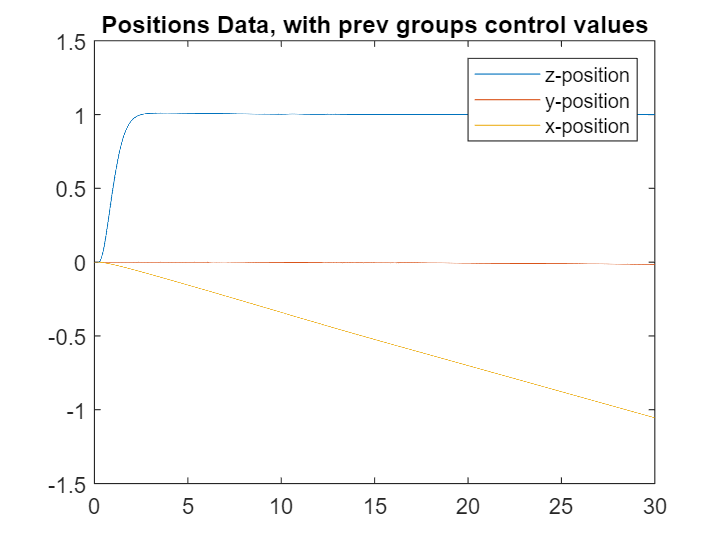

%plotting position data
clf
positionData=simout.logsout.getElement("Position").Values.Data;
t=simout.logsout.getElement("Position").Values.Time;
plot(t,positionData)
title("Positions Data, with prev groups control values")
legend("z-position","y-position","x-position")

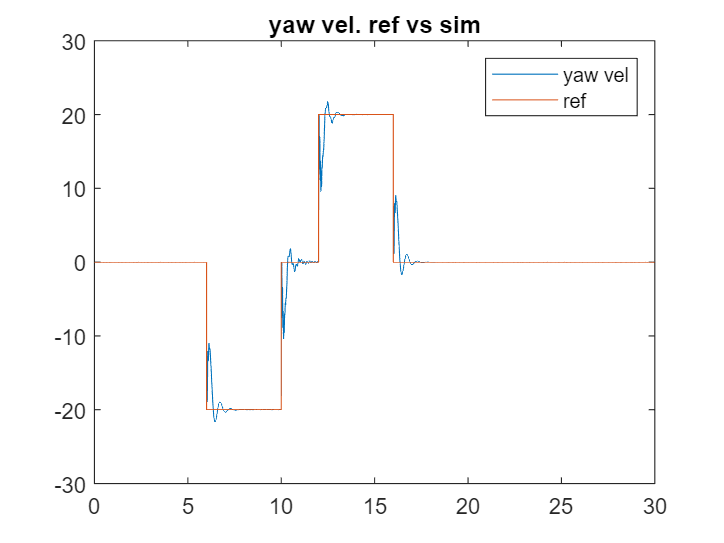


%yaw
yawData=simout.logsout.getElement("yaw vel").Values.Data;
uYawData=simout.logsout.getElement("u-yaw").Values.Data;
yawRefData=simout.logsout.getElement("yaw vel ref").Values.Data;
plot(t,[yawData,yawRefData])
title("yaw vel. ref vs sim")
legend("yaw vel","ref")

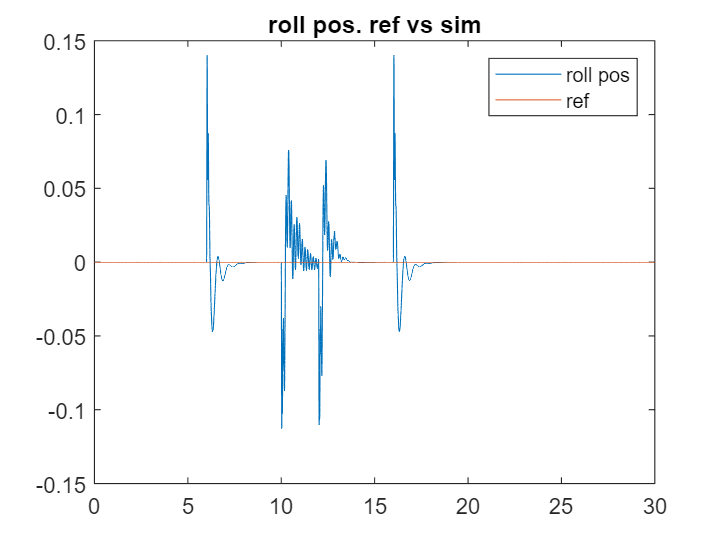


%roll
rollData=simout.logsout.getElement("roll deg").Values.Data;
urollData=simout.logsout.getElement("u-roll").Values.Data;
rollRefData=simout.logsout.getElement("roll deg ref").Values.Data;
plot(t,[rollData,rollRefData])
title("roll pos. ref vs sim")
legend("roll pos","ref")

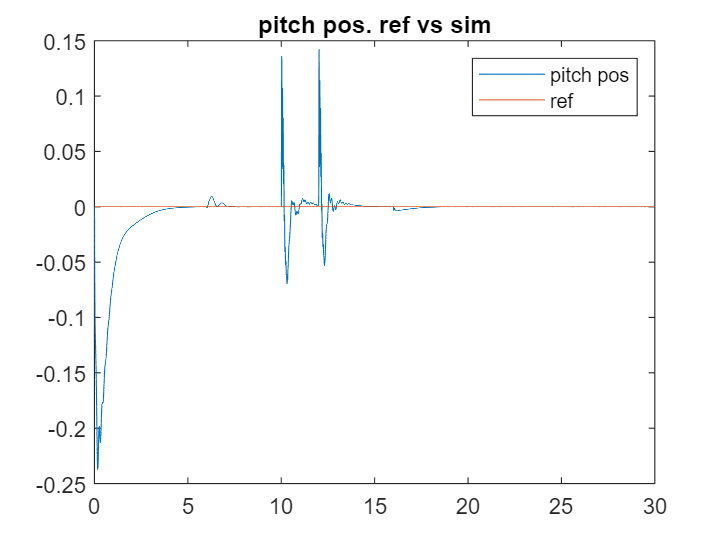


%pitch
pitchData=simout.logsout.getElement("pitch deg").Values.Data;
upitchData=simout.logsout.getElement("u-pitch").Values.Data;
pitchRefData=simout.logsout.getElement("pitch deg ref").Values.Data;
plot(t,[pitchData,pitchRefData])
title("pitch pos. ref vs sim")
legend("pitch pos","ref")